data = load("aug4signs_trainingdata_new.mat");

signsDataset = data.trainingData;

summary(signsDataset)

Variables:

    imageFilename: 90×1 cell array of character vectors

    TrafficSign: 90×1 cell



allBoxes = vertcat(signsDataset.TrafficSign{:});

**Plot the box area versus the box aspect ratio.**

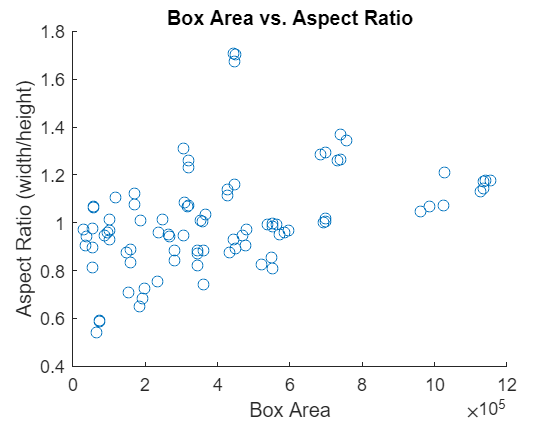

aspectRatio = allBoxes(:,3) ./ allBoxes(:,4);
area = prod(allBoxes(:,3:4),2);

figure
scatter(area,aspectRatio)
xlabel("Box Area")
ylabel("Aspect Ratio (width/height)");
title("Box Area vs. Aspect Ratio")

**Estimate Anchor Boxes**

trainingData = boxLabelDatastore(signsDataset(:,2:end));

numAnchors = 5;
[anchorBoxes,meanIoU] = estimateAnchorBoxes(trainingData,numAnchors);
anchorBoxes

anchorBoxes =          533         498
         722         692
         975        1104
         284         253
         709         913


meanIoU

meanIoU = 0.8078

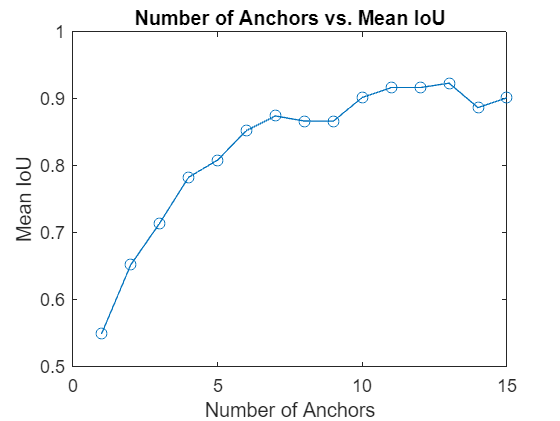

maxNumAnchors = 15;
meanIoU = zeros([maxNumAnchors,1]);
anchorBoxes = cell(maxNumAnchors, 1);
for k = 1:maxNumAnchors
    % Estimate anchors and mean IoU.
    [anchorBoxes{k},meanIoU(k)] = estimateAnchorBoxes(trainingData,k);    
end

figure
plot(1:maxNumAnchors,meanIoU,'-o')
ylabel("Mean IoU")
xlabel("Number of Anchors")
title("Number of Anchors vs. Mean IoU")